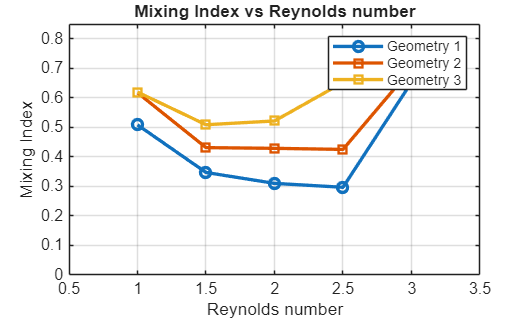

clc;
clear;

re = [1, 1.5, 2, 2.5, 3];

numCases = length(re);
MI = zeros(1, numCases);

% -------- FIRST DATASET --------
for i = 1:numCases
    
    filename = sprintf('try1_%d.csv', i);
    data = readmatrix(filename);
    
    massFraction = data(:,4);
    sigma = std(massFraction);
    
    MI(i) = 1 - (sigma / 0.5);
    
end

figure;
plot(re, MI, '-o','LineWidth',2);
hold on;


% -------- SECOND DATASET --------
MI = zeros(1, numCases);   % reset MI

for i = 1:numCases
    
    filename = sprintf('try2_%d.csv', i);
    data = readmatrix(filename);
    
    massFraction = data(:,4);
    sigma = std(massFraction);
    
    MI(i) = 1 - (sigma / 0.5);
    
end

plot(re, MI, '-s','LineWidth',2);
hold on;

MI = zeros(1, numCases);   % reset MI

for i = 1:numCases
    
    filename = sprintf('try3_%d.csv', i);
    data = readmatrix(filename);
    
    massFraction = data(:,4);
    sigma = std(massFraction);
    
    MI(i) = 1 - (sigma / 0.5);
    
end

plot(re, MI, '-s','LineWidth',2);

xlabel('Reynolds number');
xlim([0.5 3.5])
ylim([0 0.85])
ylabel('Mixing Index');
title('Mixing Index vs Reynolds number');
legend('Geometry 1','Geometry 2','Geometry 3');
datacursormode on
grid on;
hold off;